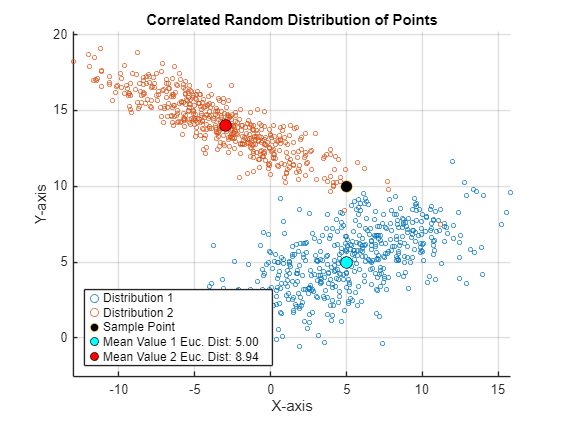

% Parameters
numPoints = 500; % Number of random points
point = [5 10];

% First Distribution
meanX1 = 5; % Mean value in the x direction
meanY1 = 5; % Mean value in the y direction
stdDevX = 4; % Standard deviation in the x direction
stdDevY = 2.2; % Standard deviation in the y direction
correlation = 0.6; % Correlation coefficient between x and y

[data, covMatrix1, ellipse, ellipse_2SD] = createDistribution(meanX1,meanY1,stdDevX,correlation,stdDevY,numPoints);
[mahalanobisDistance1,euclideanDistance1] = calculateDistances(point, meanX1,meanY1,covMatrix1);

% Second distribution
meanX2 = -3; % Mean value in the x direction
meanY2 = 14; % Mean value in the y direction
stdDevX = 4; % Standard deviation in the x direction
stdDevY = 2; % Standard deviation in the y direction
correlation = -0.9; % Correlation coefficient between x and y

[data2, covMatrix2, ellipse2, ellipse2_2SD] = createDistribution(meanX2,meanY2,stdDevX,correlation,stdDevY,numPoints);
[mahalanobisDistance2,euclideanDistance2] = calculateDistances(point, meanX2,meanY2,covMatrix2);

% Plot 1 Labelling Just Euclidean Distances
PLOTID = 1;
createPlot(data,data2,point,meanX1,meanX2,meanY1,meanY2,ellipse,ellipse2,ellipse_2SD,ellipse2_2SD,euclideanDistance1, euclideanDistance2,PLOTID)

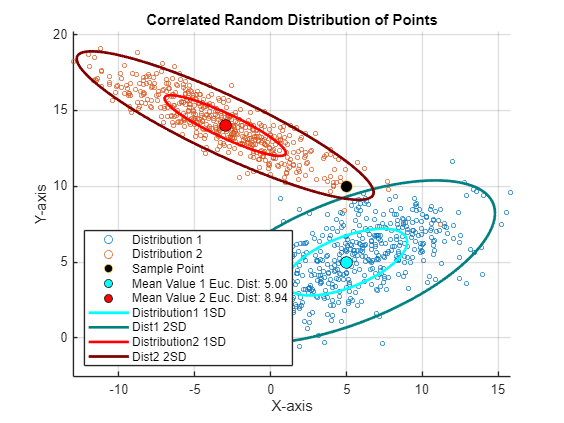

% Plot 2 Labelling Mahalanobis Distances
PLOTID = 2;
createPlot(data,data2,point,meanX1,meanX2,meanY1,meanY2,ellipse,ellipse2,ellipse_2SD,ellipse2_2SD,euclideanDistance1, euclideanDistance2,PLOTID)

Bar Graph for comparing the Euclidean Distance to the Mahalanobis Distance

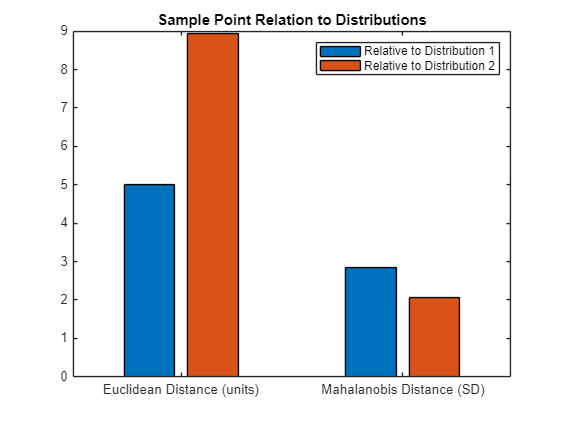

figure;
bar([ euclideanDistance1 euclideanDistance2;  mahalanobisDistance1 mahalanobisDistance2])
xticklabels({'Euclidean Distance (Units)','Mahalanobis Distance (SD)'})
legend({'Relative to Distribution 1','Relative to Distribution 2'}, 'Location','northeast')
title('Sample Point Relation to Distributions')

**createDistribution**

function [data, covMatrix1, ellipse, ellipse_2SD] = createDistribution(meanX1, meanY1,stdDevX,correlation,stdDevY,numPoints)
% Covariance matrix
covMatrix1 = [stdDevX^2, correlation * stdDevX * stdDevY; 
             correlation * stdDevX * stdDevY, stdDevY^2];
% Create Ellipse for Plotting
[ellipse, ellipse_2SD] = createEllipse(covMatrix1);

% Generate correlated random points
data = mvnrnd([meanX1, meanY1], covMatrix1, numPoints);
end

**calculateDistances**

function [mahalanobisDistance1,euclideanDistance1] = calculateDistances(point, meanX1,meanY1,covMatrix1)
pointDist1 = [meanX1 meanY1];
diff = point - pointDist1; % Difference between the point and the mean
mahalanobisDistance1 = sqrt(diff / covMatrix1 * diff');
euclideanDistance1 = sqrt(sum((point - pointDist1).^2));
end

**createEllipse**

function [ellipse, ellipse2SD] = createEllipse(covMatrix)
% Eigen values of measurement noise
[V, D] = eig(covMatrix); 

% 1SD:
% Calculate sides of ellipse (multiplying by sqrt(5.991) gives 2 SD)
chi_square_val = 1; %sqrt(5.991);
a = chi_square_val * sqrt(D(1,1)); % semi-major axis
b = chi_square_val * sqrt(D(2,2)); % semi-minor axis

% Create ellipse points
theta = linspace(0, 2*pi, 100);
ellipse_x = a * cos(theta);
ellipse_y = b * sin(theta);
ellipse = V * [ellipse_x; ellipse_y];

% 2SD:
% Calculate sides of ellipse (multiplying by sqrt(5.991) gives 2 SD)
chi_square_val = sqrt(5.991);
a = chi_square_val * sqrt(D(1,1)); % semi-major axis
b = chi_square_val * sqrt(D(2,2)); % semi-minor axis

% Create ellipse points
theta = linspace(0, 2*pi, 100);
ellipse_x = a * cos(theta);
ellipse_y = b * sin(theta);
ellipse2SD = V * [ellipse_x; ellipse_y];

end


**createPlot**

function createPlot(data,data2,point,meanX1,meanX2,meanY1,meanY2,ellipse,ellipse2,ellipse_2SD,ellipse2_2SD,euclideanDistance1, euclideanDistance2, PLOTID)
% Plot
figure; hold on;
scatter(data(:,1), data(:,2), 10); % Plot the scatter of points of Distribution 1
scatter(data2(:,1), data2(:,2), 10); % Plot the scatter of points of Distribution 2

scatter(point(1),point(2),75,'MarkerEdgeColor','flat','MarkerFaceColor','k')% Plot the Sample Point

% Plot the Mean Values
scatter(meanX1,meanY1,75,'MarkerEdgeColor','k','MarkerFaceColor','c')
scatter(meanX2,meanY2,75,'MarkerEdgeColor','k','MarkerFaceColor','r')

if PLOTID == 2
    % Create colors darker than standard to differentiate between 1 and 2SD
    originalCyan = [0, 1, 1]; % Original cyan color
    darkerCyan = originalCyan * 0.5; % Scale down the brightness -% Darker cyan color
    originalRed = [1, 0, 0]; % Original red color
    darkerRed = originalRed * 0.5; % Scale down the brightness - % Darker red color

    % Add ellipse for 1SD and 2SD Mahalanobis Distances
    plot(meanX1 + ellipse(1, :), meanY1 + ellipse(2, :), 'c', 'LineWidth', 2);
    plot(meanX1 + ellipse_2SD(1, :), meanY1 + ellipse_2SD(2, :),'Color', darkerCyan, 'LineWidth', 2);
    plot(meanX2 + ellipse2(1, :), meanY2 + ellipse2(2, :), 'r', 'LineWidth', 2);
    plot(meanX2 + ellipse2_2SD(1, :), meanY2 + ellipse2_2SD(2, :),'Color', darkerRed,  'LineWidth', 2);
end

% Format Plot
title('Correlated Random Distribution of Points');
xlabel('X-axis');
ylabel('Y-axis');
axis equal;
grid on;
hold on;

if PLOTID==1
legend({'Distribution 1','Distribution 2','Sample Point',...
    sprintf('Mean Value 1 Euc. Dist: %.2f', euclideanDistance1),...
    sprintf('Mean Value 2 Euc. Dist: %.2f', euclideanDistance2)},...
    'Location','southwest')
else
    legend({'Distribution 1','Distribution 2','Sample Point',...
        sprintf('Mean Value 1 Euc. Dist: %.2f', euclideanDistance1),...
        sprintf('Mean Value 2 Euc. Dist: %.2f', euclideanDistance2),...
        'Distribution1 1SD', 'Dist1 2SD',...
        'Distribution2 1SD', 'Dist2 2SD'},...
        'Location','southwest')
end

end